# Exercise 4: Identify Position Limits

## Define motor specifications

The motor specification sheet provides details about the particular motors you are using. They are rated at 6 V and 12 V. We'll use the 12 V values, but you should get the same results if you use the 6 V values. First, define the rated voltage.

V_rated = 12; %Volts

The free-run speed is the speed of the motor with no load. At 12 V it is defined as 300 rpm. Convert this to SI units, i.e., radians per second, to make all calculations consistent. To do so, multiply by the following conversion factors:

$\frac{2\pi \;\textrm{rad}}{1\;\textrm{rev}}$ and $\frac{1\;\min }{60\;\sec }$

w_free = 300;            %rev/min
w_free = w_free*2*pi/60; %rad/s

The spec page also provides the stall torque at the rated voltage as 2220 g-cm. The g in this context refers to gram-force, rather than gram mass. You can look up for the conversion factor to convert this torque to SI units of N-m, or you can use the convenient `unitConversionFactor` function from Symbolic Math Toolbox.

u = symunit;
TauStall = 2.220; %kg-cm
TauStall = TauStall*double(unitConversionFactor(u.kgf*u.cm,u.Nm)); %N-m

## Calculate motor constants from specs

Under free-run conditions, the torque equation simplifies to $V=\omega_{\textrm{free}} k$. Use this relationship and the known values for *V* and $\omega_{\textrm{free}}$ to calculate the motor constant *k*.

k = V_rated/w_free; %V-s (or N-m/A)clear

Under stall conditions, $\omega =0$, and the torque equation simplifies to $\tau_{\textrm{stall}} =\frac{\textrm{Vk}}{R}$. Use this relationship and the known values for $\tau_{\textrm{stall}}$, *V*, and *k* to calculate the motor resistance *R*.

R = V_rated*k/TauStall; %Ohm

## Calculate torque limit for available voltage

The whiteboard robot will not be operating at the rated voltage of 12 V. You will instead be using a battery. The battery provided with the kit is rated at 3.7 V. Define this value as the available voltage for your battery.

V_battery = 3.7; %Volts

Consider the stall condition for your whiteboard robot with the given battery and motor constants. Calculate the theoretical stall torque for your battery.


$$\tau_{\textrm{stall}} =\frac{{\mathrm{V}}_{\textrm{battery}} \mathrm{k}}{R}$$


It's recommended not to exceed 30% of the stall torque of the motor. Given this constraint, calculate the maximum allowable torque to apply to the motor.


$$\tau_{\max } =0\ldotp 3\tau_{\textrm{stall}} =0\ldotp 3\frac{{\mathrm{V}}_{\textrm{battery}} \mathrm{k}}{R}$$


TauMax = 0.3*V_battery*k/R %Do not exceed 30% of the stall torque

TauMax = 0.0201

## Define whiteboard dimensions

Next, you will identify all the positions on the whiteboard and determine which one of them the robot will be allowed to reach. First, you need to define the dimensions of the whiteboard. You've already defined the *Base* dimension in a previous task and saved it in the MAT-file RobotGeometry.mat. You will also need to define the height of the whiteboard. Measure this height using a tape or a meterstick, and record it in the `H_board` variable below.

H_board = 0.6; %Change this to the height value for your whiteboard (meters)
% load RobotGeometry.mat Base
Base = 1;

## 4: Create a grid of all possible board positions

The meshgrid command allows you to create a grid of coodinates. It takes as input arguments an array of x and y positions. Define the x-positions as an array of values from 0 to Base with a resolution of 1 mm. Define the y-positions from 1 mm to `H_board` with a resolution of 1 mm. Do not start y with zero. The tension at y = 0 will always be infinite because the robot would not be supported from above.

xarray = 0:0.001:Base;
yarray = 0.001:0.001:H_board;

Create the grid of *x* and *y* values from these arrays.

[X,Y] = meshgrid(xarray,yarray);

## Define robot constants for calculating torque

To compute torque at every point on the grid, you need some additional constants related to the robot. These values should be true for your kit, but you can take your own measurements and change the values below if you find them to be inaccurate.

r_spool = 0.0045;   %m
Mass = 0.25;       %kg (You can modify this based on the actual weight of your robot.)
Weight = Mass*9.81; %N

## Compute torque at every position

Combine all your equations from geometry, trigonometry, linear mechanics, and rotational mechanics to compute the motor torque at every position on the whiteboard. Apply these equations element-wise so that they apply to all points in the grid at the same time.

From the trigonometic function definitions:

theta1 = atan(X./Y);
theta2 = atan((Base-X)./Y);

From the free-body diagram and Newton's Third Law of Motion:

F1 = Weight*sin(theta2)./(sin(theta1).*cos(theta2) + sin(theta2).*cos(theta1));
F2 = Weight*sin(theta1)./(sin(theta1).*cos(theta2) + sin(theta2).*cos(theta1));

From the definition of tension applied at multiple points:

T1 = F1/2;
T2 = F2/2;

From the definition of torque:

Tau1 = T1*r_spool;
Tau2 = T2*r_spool;

Create one grid that stores the largest torque on either of the motors at every point.

Tau = max(Tau1,Tau2);

## Plot torque at every position

Create and label a surface plot to visualize the torque at every point on the whiteboard.

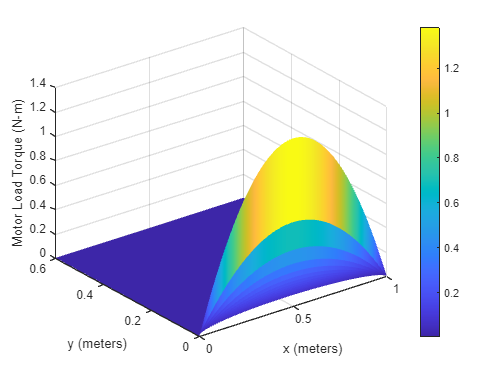

surf(X,Y,Tau,'EdgeColor','none')
xlabel('x (meters)')
ylabel('y (meters)')
zlabel('Motor Load Torque (N-m)')
colorbar

## Eliminate bad regions

Define some distance constants that can be used to identify unreachable regions of the whiteboard, where the robot would be either too close to the pulleys or too close to the bottom of the whiteboard.

pulleyBuffer = 0.05; %Minimum distance to pulley (meters)
L_arm = 0.075;       %meters
H_robot = 0.19;      %meters
r_pulley = 0.0075;   %meters

Create a transparency mask to make the plot transparent in areas that the robot will not be allowed to reach.

opacity = ones(size(X));

Remove positions where the torque is too high. Use a logical index to define these regions as 0.

opacity(Tau > TauMax) = 0;

Remove positions where the robot is too close to the pulleys.

nearLeftPulley = X.^2 + Y.^2 <= (L_arm + r_pulley + pulleyBuffer).^2;
nearRightPulley = (Base-X).^2 + Y.^2 <= (L_arm + r_pulley + pulleyBuffer).^2;
opacity(nearLeftPulley | nearRightPulley) = 0;

Remove positions where the robot is too close to the bottom of the board.

nearBottom = Y > H_board - H_robot;
opacity(nearBottom) = 0;

## Plot torque in allowable regions

Now plot the torque again, but use the `imagesc` function to draw it as an image and scale the data to the figure's colormap. Use the opacity variable to display only parts of the image that the robot is allowed to reach. Rescale the colormap so it only goes as high as the torque limit.

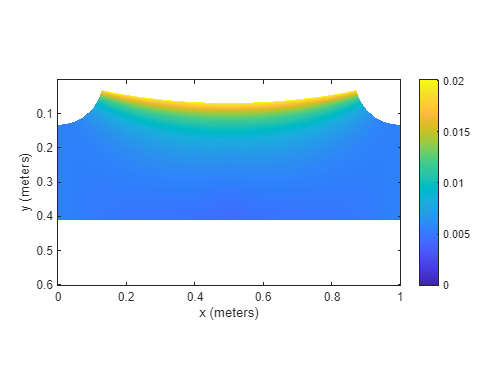

imagesc(xarray,yarray,Tau,'AlphaData',opacity)
xlabel('x (meters)')
ylabel('y (meters)')
colorbar
ax = gca;
ax.CLim = [0 TauMax];
ax.XLim = [0 Base];
ax.YLim = [0 H_board];
axis equal tight

## Choose drawable region limits and visualize

After choosing a point as the minimum *xy*-coordinate, enter it in the following section of code. Execute this section to visualize the drawable area.

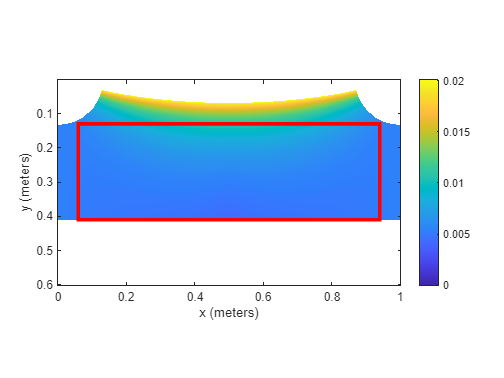

pickedX = 0.06; %Change this to your chosen minimum x-value (meters)
pickedY = 0.13; %Change this to your chosen minimum y-value (meters)
xLim = [pickedX Base-pickedX];
yLim = [pickedY H_board-H_robot];
hold on
rectangle('Position',[xLim(1) yLim(1) diff(xLim) diff(yLim)],...
    'EdgeColor','red','LineWidth',3)
hold off

## Save chosen drawing limits

Save `xLim` and `yLim` for use in future exercises.

save WhiteboardLimits.mat xLim yLim

*Copyright 2018 - 2020 The MathWorks, Inc.*